Loading the data

dataFolder = '/data/compact';
captureName = 'compact2.frames';
tag1Hz = 64;
tag2Hz = 105;

[compactFrameTot, compactFramesBB, frameRate] = ProcessFrames(dataFolder, captureName);
[compactCaptureFT, compactTag1FT] = ProcessFFT(compactFramesBB, frameRate, tag1Hz);
[~, compactTag2FT] = ProcessFFT(compactFramesBB, frameRate, tag2Hz);
[compactPeakBin1] = TagLocateCWT(compactTag1FT, false);
[compactPeakBin2] = TagLocateCWT(compactTag2FT, false);

dataFolder = '/data/compact';
captureName = 'loose2.frames';

[looseFrameTot, looseFramesBB, ~] = ProcessFrames(dataFolder, captureName);
[looseCaptureFT, looseTag1FT] = ProcessFFT(looseFramesBB, frameRate, tag1Hz);
[~, looseTag2FT] = ProcessFFT(looseFramesBB, frameRate, tag2Hz);
[loosePeakBin1] = TagLocateCWT(looseTag1FT, false);
[loosePeakBin2] = TagLocateCWT(looseTag2FT, false);


Plotting the median frames

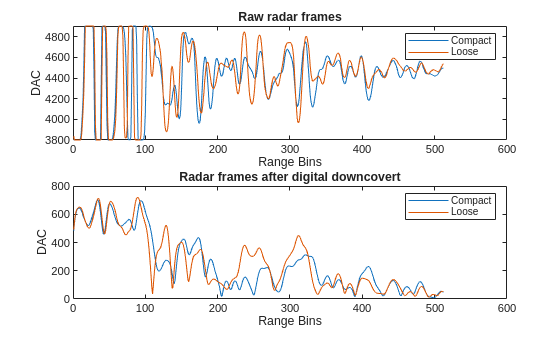

figure

subplot(2,1,1)
plot(median(compactFrameTot, 2))
hold on
plot(median(looseFrameTot, 2))
legend(["Compact", "Loose"])
xlabel('Range Bins')
ylabel('DAC')
title('Raw radar frames')

subplot(2,1,2)
plot(median(abs(compactFramesBB), 2))
hold on
plot(median(abs(looseFramesBB), 2))
legend(["Compact", "Loose"])
xlabel('Range Bins')
ylabel('DAC')
title('Radar frames after digital downcovert')

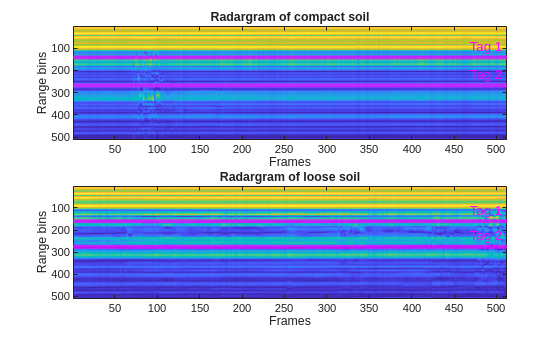

compactFrameNorm = abs(compactFramesBB ./ max(max(compactFramesBB)));
compactFrameNorm = imresize(compactFrameNorm, [512 512]);
looseFrameNorm = abs(looseFramesBB ./ max(max(looseFramesBB)));
looseFrameNorm = imresize(looseFrameNorm, [512 512]);

figure

subplot(2,1,1)
compactRadargram = imagesc(abs(compactFrameNorm));
xlabel("Frames")
ylabel("Range bins")
title("Radargram of compact soil")
yline(compactPeakBin1, '-', 'Tag 1', 'Color', [1 0 1], 'LineWidth', 3)
yline(compactPeakBin2, '-', 'Tag 2', 'Color', [1 0 1], 'LineWidth', 3)

subplot(2,1,2)
imagesc(abs(looseFrameNorm))
xlabel("Frames")
ylabel("Range bins")
title("Radargram of loose soil")
yline(loosePeakBin1, '-', 'Tag 1', 'Color', [1 0 1], 'LineWidth', 3)
yline(loosePeakBin2, '-', 'Tag 2', 'Color', [1 0 1], 'LineWidth', 3)


imwrite(compactFrameNorm, "compact.png")
imwrite(looseFrameNorm, "loose.png")


% figure
% subplot(2,1,1)
% [s, f, t] = stft(median(compactFramesBB, 2));
% % mesh(t, f, abs(s).^2);
% imagesc(abs(s))
% subplot(2,1,2)
% s = stft(median(looseFramesBB, 2));
% imagesc(abs(s))
% % imagesc(abs(s))